stock_data_file = "C:/Users/vignesh.subramanian/Desktop/stockPredictor/data/stockdata";
history_weeks = 52;
skip_weeks = 14; %Rebalance quarterly
max_weeks = Inf;
max_sane_return = 1;

real_budget = 100000;
scale_factor = 0.01;
min_stocks = 10;
max_stocks = 20;
min_fraction = 0.02;
max_fraction = 0.1;
min_fraction_invested = 0.8;
lambda = 0.001;


[num,txt] = xlsread(stock_data_file);
price_dates_string =txt(7:min(max_weeks, size(txt,1)),1);
price_dates_number = floor(datenum(price_dates_string));
first_date = price_dates_number(1);
price_dates_number = price_dates_number - first_date+1;
stock_tickers = txt(4,2:end);
stock_price_matrix = num(5:min(max_weeks, size(num,1)), :);

stock_returns_matrix = zeros(size(stock_price_matrix)-[1,0]);
for j = 2:size(stock_price_matrix,1)
    for i = 1:size(stock_price_matrix,2)
           if stock_price_matrix(j-1,1) > 0
               cur_return =  stock_price_matrix(j,i)./stock_price_matrix(j-1,i) -1;
           else
               cur_return = 0;
           end
           if(abs(cur_return)>max_sane_return)
               cur_return = max_sane_return*(cur_return)/abs(cur_return);
           end
           stock_returns_matrix(j-1,i) = cur_return;
    end
end
% stock_returns_matrix

% disp(stock_tickers)
total_weeks = size(price_dates_number,1);
current_budget = real_budget;
alt_current_budget = real_budget;
budget_vector = [current_budget];
alt_budget_vector = [alt_current_budget];
asset_allocation_vector = {};
asset_quantity_vector = {};
for i = 1:size(stock_price_matrix,2)
    asset_allocation_vector{i} = [];
    asset_quantity_vector{i} = [];
end
last_index = -1

last_index = -1

last_allocation = []


last_allocation =

     []



last_quantity = []


last_quantity =

     []



for cur_week_index = history_weeks:skip_weeks:total_weeks-1
    last_index = cur_week_index
    disp(" ")
    cur_date_split = strsplit(char(price_dates_string(cur_week_index)), ' ');
    cur_date = cur_date_split{1}  
    start_week_index = cur_week_index - history_weeks+1
    cur_week_index
    cur_returns_matrix = stock_returns_matrix(start_week_index:cur_week_index,:);
    
    [mean_vector, covariance_matrix] = get_mean_covariance(cur_returns_matrix);
    

    price_vector = stock_price_matrix(cur_week_index, :);
%     mean_vector(isnan(mean_vector))=-555;
%     price_vector(isnan(price_vector)) = 1;
%     covariance_matrix(isnan(covariance_matrix)) = 555;
    
    [ objective_value, allocation_vector, quantity_vector ] = sovle_miqp(mean_vector, covariance_matrix, price_vector, current_budget, scale_factor, min_stocks, max_stocks, min_fraction, max_fraction, min_fraction_invested, lambda, max_sane_return );
    [alt_objective_value, alt_allocation_vector, alt_quantity_vector] = solve_qp(mean_vector, covariance_matrix, price_vector, alt_current_budget, min_stocks, max_stocks, min_fraction, max_fraction, lambda, max_sane_return ) ;
    
%     figure; bar(allocation_vector)
%     title('Allocation vector')
%     figure; bar(alt_allocation_vector)
%     title('Alt allocation')
%     
    last_quantity = quantity_vector;
    last_allocation = allocation_vector;
%     allocation_vector = 100*ones(size(allocation_vector))/size(allocation_vector, 1)
    disp([cur_week_index, history_weeks, total_weeks])
    
    for i = 1:size(stock_price_matrix,2)
       asset_quantity_vector{i} = [asset_quantity_vector{i}, quantity_vector(i)];
       asset_allocation_vector{i} = [asset_allocation_vector{i}, current_budget*allocation_vector(i)/100];
       
    
    end
    if cur_week_index + skip_weeks <= total_weeks
        
%         sum(allocation_vector)
        future_profit =  get_future_profit(allocation_vector, current_budget, cur_week_index, skip_weeks, stock_price_matrix, max_sane_return);
        current_budget = current_budget + future_profit;
        disp("Future Profit: " + num2str(future_profit))
        
       
        alt_future_profit =  get_future_profit(alt_allocation_vector, alt_current_budget, cur_week_index, skip_weeks, stock_price_matrix, max_sane_return);
        alt_current_budget = alt_current_budget + alt_future_profit;
        disp("Alt Future Profit: " + num2str(alt_future_profit))
%         figure; bar(alt_allocation_vector)
%         title(num2str(alt_future_profit))
    end
    
   disp("Current budget: " + num2str(current_budget))
   budget_vector = [budget_vector; current_budget];
  
   disp("Alt current budget: " + num2str(alt_current_budget))
   alt_budget_vector = [alt_budget_vector; alt_current_budget];
  
       
   
end

last_index = 52

cur_date = '6/7/2013'

start_week_index = 1

cur_week_index = 52

The expected return is 6.78194, and the risk-adjusted return is 6.33961.


 
Calling sedumi: 90 variables, 60 equality constraints
------------------------------------------------------------
SeDuMi 1.21 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 60, order n = 62, dim = 91, blocks = 2
nnz(A) = 554 + 0, nnz(ADA) = 1920, nnz(L) = 990
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.45E+03 0.000
  1 :  -5.73E+03 7.67E+02 0.000 0.5275 0.9000 0.9000   5.13  1  1  8.3E+00
  2 :  -1.40E+03 3.51E+02 0.000 0.4579 0.9000 0.9000   2.73  1  1  2.5E+00
  3 :  -8.71E+02 1.54E+02 0.000 0.4373 0.9000 0.9000   1.48  1  1  1.0E+00
  4 :  -5.02E+02 6.66E+01 0.000 0.4340 0.9000 0.9000   1.12  1  1  5.1E-01
  5 :  -2.76E+02 2.83E+01 0.000 0.4255 0.9000 0.9000   0.97  1  1  2.8E-01
  6 :  -1.52E+02 1.14E+01 0.000 0.4027 0.9000 0.9024   0.91  1  1  1.7E-01
  7 :  -9.04E+01 4.72E+00 0.000 0.4135 0.9000 0.9011   0.86  1  1  1.1E-01
  8 :  -6.10E+0

    52    52   283



Future Profit: -7424


Alt Future Profit: 3309


Current budget: 92576


Alt current budget: 103309


last_index = 66

cur_date = '9/13/2013'

start_week_index = 15

cur_week_index = 66

The expected return is 5.37116, and the risk-adjusted return is 5.13782.


 
Calling sedumi: 90 variables, 60 equality constraints
------------------------------------------------------------
SeDuMi 1.21 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 60, order n = 62, dim = 91, blocks = 2
nnz(A) = 554 + 0, nnz(ADA) = 1920, nnz(L) = 990
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.71E+03 0.000
  1 :  -6.94E+03 8.72E+02 0.000 0.5106 0.9000 0.9000   5.22  1  1  7.6E+00
  2 :  -1.74E+03 4.14E+02 0.000 0.4744 0.9000 0.9000   2.79  1  1  2.5E+00
  3 :  -9.62E+02 1.79E+02 0.000 0.4335 0.9000 0.9000   1.48  1  1  1.0E+00
  4 :  -5.29E+02 7.73E+01 0.000 0.4310 0.9000 0.9000   1.10  1  1  5.0E-01
  5 :  -2.88E+02 3.28E+01 0.000 0.4237 0.9000 0.9000   0.96  1  1  2.8E-01
  6 :  -1.63E+02 1.33E+01 0.000 0.4069 0.9000 0.9022   0.89  1  1  1.7E-01
  7 :  -1.03E+02 5.60E+00 0.000 0.4202 0.9000 0.9010   0.83  1  1  1.1E-01
  8 :  -7.68E+0

    66    52   283



Future Profit: 16759


Alt Future Profit: 11069


Current budget: 109335


Alt current budget: 114378


last_index = 80

cur_date = '12/27/2013'

start_week_index = 29

cur_week_index = 80

The expected return is 9.7006, and the risk-adjusted return is 9.2813.


 
Calling sedumi: 90 variables, 60 equality constraints
------------------------------------------------------------
SeDuMi 1.21 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 60, order n = 62, dim = 91, blocks = 2
nnz(A) = 554 + 0, nnz(ADA) = 1920, nnz(L) = 990
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.80E+03 0.000
  1 :  -7.84E+03 9.16E+02 0.000 0.5076 0.9000 0.9000   5.22  1  1  7.5E+00
  2 :  -2.10E+03 4.36E+02 0.000 0.4764 0.9000 0.9000   2.77  1  1  2.4E+00
  3 :  -1.21E+03 1.91E+02 0.000 0.4388 0.9000 0.9000   1.47  1  1  1.0E+00
  4 :  -7.04E+02 8.36E+01 0.000 0.4367 0.9000 0.9000   1.09  1  1  5.0E-01
  5 :  -4.16E+02 3.60E+01 0.000 0.4312 0.9000 0.9000   0.93  1  1  2.7E-01
  6 :  -2.66E+02 1.57E+01 0.000 0.4356 0.9000 0.9000   0.85  1  1  1.6E-01
  7 :  -1.84E+02 7.02E+00 0.000 0.4469 0.9000 0.9000   0.76  1  1  1.0E-01
  8 :  -1.66E+0

    80    52   283



Future Profit: 7979


Alt Future Profit: -1440


Current budget: 117314


Alt current budget: 112938


last_index = 94

cur_date = '4/11/2014'

start_week_index = 43

cur_week_index = 94

The expected return is 12.6408, and the risk-adjusted return is 12.0349.


 
Calling sedumi: 90 variables, 60 equality constraints
------------------------------------------------------------
SeDuMi 1.21 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 60, order n = 62, dim = 91, blocks = 2
nnz(A) = 554 + 0, nnz(ADA) = 1920, nnz(L) = 990
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.37E+03 0.000
  1 :  -8.17E+03 7.01E+02 0.000 0.5112 0.9000 0.9000   5.24  1  1  7.5E+00
  2 :  -2.45E+03 3.46E+02 0.000 0.4938 0.9000 0.9000   2.79  1  1  2.5E+00
  3 :  -1.42E+03 1.53E+02 0.000 0.4433 0.9000 0.9000   1.48  1  1  1.1E+00
  4 :  -8.46E+02 6.74E+01 0.000 0.4398 0.9000 0.9000   1.08  1  1  5.1E-01
  5 :  -5.17E+02 2.93E+01 0.000 0.4345 0.9000 0.9000   0.91  1  1  2.6E-01
  6 :  -3.39E+02 1.28E+01 0.000 0.4378 0.9000 0.9000   0.82  1  1  1.5E-01
  7 :  -2.36E+02 5.73E+00 0.000 0.4463 0.9000 0.9000   0.73  1  1  9.3E-02
  8 :  -2.07E+0

    94    52   283



Future Profit: 33139


Alt Future Profit: 6367


Current budget: 150453


Alt current budget: 119305


last_index = 108

cur_date = '7/18/2014'

start_week_index = 57

cur_week_index = 108

The expected return is 21.8415, and the risk-adjusted return is 19.7533.


 
Calling sedumi: 90 variables, 60 equality constraints
------------------------------------------------------------
SeDuMi 1.21 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 60, order n = 62, dim = 91, blocks = 2
nnz(A) = 554 + 0, nnz(ADA) = 1920, nnz(L) = 990
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.17E+03 0.000
  1 :  -8.06E+03 6.03E+02 0.000 0.5143 0.9000 0.9000   5.19  1  1  7.7E+00
  2 :  -2.42E+03 2.88E+02 0.000 0.4770 0.9000 0.9000   2.73  1  1  2.4E+00
  3 :  -1.52E+03 1.29E+02 0.000 0.4481 0.9000 0.9000   1.48  1  1  1.0E+00
  4 :  -9.71E+02 5.78E+01 0.000 0.4487 0.9000 0.9000   1.08  1  1  4.9E-01
  5 :  -6.37E+02 2.57E+01 0.000 0.4447 0.9000 0.9000   0.90  1  1  2.5E-01
  6 :  -4.45E+02 1.14E+01 0.000 0.4448 0.9000 0.9000   0.79  1  1  1.4E-01
  7 :  -3.30E+02 5.13E+00 0.000 0.4486 0.9000 0.9000   0.68  1  1  8.4E-02
  8 :  -2.93E+0

   108    52   283



Future Profit: 21874


Alt Future Profit: 3508


Current budget: 172327


Alt current budget: 122813


last_index = 122

cur_date = '10/23/2014'

start_week_index = 71

cur_week_index = 122

The expected return is 29.2581, and the risk-adjusted return is 26.0622.


 
Calling sedumi: 90 variables, 60 equality constraints
------------------------------------------------------------
SeDuMi 1.21 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 60, order n = 62, dim = 91, blocks = 2
nnz(A) = 554 + 0, nnz(ADA) = 1920, nnz(L) = 990
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.07E+03 0.000
  1 :  -7.98E+03 5.63E+02 0.000 0.5267 0.9000 0.9000   5.15  1  1  8.1E+00
  2 :  -2.48E+03 2.69E+02 0.000 0.4784 0.9000 0.9000   2.73  1  1  2.5E+00
  3 :  -1.62E+03 1.21E+02 0.000 0.4494 0.9000 0.9000   1.49  1  1  1.1E+00
  4 :  -1.05E+03 5.44E+01 0.000 0.4493 0.9000 0.9000   1.09  1  1  5.0E-01
  5 :  -6.94E+02 2.42E+01 0.000 0.4445 0.9000 0.9000   0.91  1  1  2.6E-01
  6 :  -4.84E+02 1.07E+01 0.000 0.4442 0.9000 0.9000   0.79  1  1  1.4E-01
  7 :  -3.57E+02 4.81E+00 0.000 0.4474 0.9000 0.9000   0.69  1  1  8.3E-02
  8 :  -3.13E+0

   122    52   283



Future Profit: 41392


Alt Future Profit: 3479


Current budget: 213719


Alt current budget: 126292


last_index = 136

cur_date = '1/30/2015'

start_week_index = 85

cur_week_index = 136

The expected return is 40.9621, and the risk-adjusted return is 36.4049.


 
Calling sedumi: 90 variables, 60 equality constraints
------------------------------------------------------------
SeDuMi 1.21 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 60, order n = 62, dim = 91, blocks = 2
nnz(A) = 554 + 0, nnz(ADA) = 1920, nnz(L) = 990
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.06E+03 0.000
  1 :  -9.50E+03 5.47E+02 0.000 0.5173 0.9000 0.9000   5.24  1  1  7.6E+00
  2 :  -3.18E+03 2.74E+02 0.000 0.5014 0.9000 0.9000   2.82  1  1  2.6E+00
  3 :  -1.99E+03 1.24E+02 0.000 0.4532 0.9000 0.9000   1.50  1  1  1.1E+00
  4 :  -1.30E+03 5.60E+01 0.000 0.4503 0.9000 0.9000   1.07  1  1  5.1E-01
  5 :  -8.88E+02 2.50E+01 0.000 0.4460 0.9000 0.9000   0.86  1  1  2.6E-01
  6 :  -6.51E+02 1.11E+01 0.000 0.4442 0.9000 0.9000   0.73  1  1  1.4E-01
  7 :  -5.15E+02 4.92E+00 0.000 0.4433 0.9000 0.9000   0.62  1  1  8.3E-02
  8 :  -4.41E+0

   136    52   283



Future Profit: 3146


Alt Future Profit: 1767


Current budget: 216865


Alt current budget: 128059


last_index = 150

cur_date = '5/15/2015'

start_week_index = 99

cur_week_index = 150

The expected return is 30.53, and the risk-adjusted return is 26.6374.


 
Calling sedumi: 90 variables, 60 equality constraints
------------------------------------------------------------
SeDuMi 1.21 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 60, order n = 62, dim = 91, blocks = 2
nnz(A) = 554 + 0, nnz(ADA) = 1920, nnz(L) = 990
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.49E+03 0.000
  1 :  -8.35E+03 7.98E+02 0.000 0.5346 0.9000 0.9000   5.17  1  1  8.3E+00
  2 :  -2.52E+03 3.89E+02 0.000 0.4877 0.9000 0.9000   2.78  1  1  2.7E+00
  3 :  -1.60E+03 1.73E+02 0.000 0.4437 0.9000 0.9000   1.52  1  1  1.1E+00
  4 :  -1.00E+03 7.63E+01 0.000 0.4420 0.9000 0.9000   1.10  1  1  5.3E-01
  5 :  -6.34E+02 3.34E+01 0.000 0.4372 0.9000 0.9000   0.92  1  1  2.7E-01
  6 :  -4.27E+02 1.46E+01 0.000 0.4371 0.9000 0.9000   0.82  1  1  1.5E-01
  7 :  -3.15E+02 6.43E+00 0.000 0.4409 0.9000 0.9000   0.71  1  1  9.0E-02
  8 :  -2.61E+0

   150    52   283



Future Profit: 14596


Alt Future Profit: 5868


Current budget: 231461


Alt current budget: 133927


last_index = 164

cur_date = '8/21/2015'

start_week_index = 113

cur_week_index = 164

The expected return is 21.8392, and the risk-adjusted return is 18.7345.


 
Calling sedumi: 90 variables, 60 equality constraints
------------------------------------------------------------
SeDuMi 1.21 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 60, order n = 62, dim = 91, blocks = 2
nnz(A) = 554 + 0, nnz(ADA) = 1920, nnz(L) = 990
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.14E+03 0.000
  1 :  -7.83E+03 1.17E+03 0.000 0.5485 0.9000 0.9000   5.12  1  1  8.9E+00
  2 :  -2.01E+03 5.62E+02 0.000 0.4797 0.9000 0.9000   2.79  1  1  2.8E+00
  3 :  -1.24E+03 2.43E+02 0.000 0.4319 0.9000 0.9000   1.54  1  1  1.2E+00
  4 :  -6.97E+02 1.04E+02 0.000 0.4270 0.9000 0.9000   1.14  1  1  5.5E-01
  5 :  -3.76E+02 4.35E+01 0.000 0.4197 0.9000 0.9000   0.99  1  1  3.0E-01
  6 :  -2.11E+02 1.80E+01 0.000 0.4136 0.9000 0.9007   0.92  1  1  1.8E-01
  7 :  -1.34E+02 7.61E+00 0.000 0.4230 0.9000 0.9003   0.85  1  1  1.2E-01
  8 :  -1.00E+0

   164    52   283



Future Profit: 1028


Alt Future Profit: -1103


Current budget: 232489


Alt current budget: 132824


last_index = 178

cur_date = '11/27/2015'

start_week_index = 127

cur_week_index = 178

The expected return is 14.9758, and the risk-adjusted return is 11.6926.


 
Calling sedumi: 90 variables, 60 equality constraints
------------------------------------------------------------
SeDuMi 1.21 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 60, order n = 62, dim = 91, blocks = 2
nnz(A) = 554 + 0, nnz(ADA) = 1920, nnz(L) = 990
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.20E+03 0.000
  1 :  -8.12E+03 1.19E+03 0.000 0.5422 0.9000 0.9000   5.16  1  1  8.7E+00
  2 :  -2.03E+03 5.77E+02 0.000 0.4830 0.9000 0.9000   2.81  1  1  2.8E+00
  3 :  -1.19E+03 2.48E+02 0.000 0.4298 0.9000 0.9000   1.54  1  1  1.1E+00
  4 :  -6.33E+02 1.05E+02 0.000 0.4236 0.9000 0.9000   1.14  1  1  5.5E-01
  5 :  -3.19E+02 4.35E+01 0.000 0.4142 0.9000 0.9000   1.00  1  1  3.0E-01
  6 :  -1.61E+02 1.76E+01 0.000 0.4049 0.9000 0.9008   0.94  1  1  1.9E-01
  7 :  -8.89E+01 7.24E+00 0.000 0.4108 0.9000 0.9003   0.90  1  1  1.3E-01
  8 :  -5.78E+0

   178    52   283



Future Profit: -18246


Alt Future Profit: -262


Current budget: 214243


Alt current budget: 132562


last_index = 192

cur_date = '3/4/2016'

start_week_index = 141

cur_week_index = 192

The expected return is 5.53567, and the risk-adjusted return is 3.59939.


 
Calling sedumi: 90 variables, 60 equality constraints
------------------------------------------------------------
SeDuMi 1.21 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 60, order n = 62, dim = 91, blocks = 2
nnz(A) = 554 + 0, nnz(ADA) = 1920, nnz(L) = 990
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.46E+03 0.000
  1 :  -5.51E+03 1.33E+03 0.000 0.5417 0.9000 0.9000   4.97  1  1  9.3E+00
  2 :  -1.07E+03 5.51E+02 0.000 0.4142 0.9000 0.9000   2.69  1  1  2.5E+00
  3 :  -7.75E+02 2.38E+02 0.000 0.4320 0.9000 0.9000   1.43  1  1  1.1E+00
  4 :  -4.30E+02 1.01E+02 0.000 0.4253 0.9000 0.9000   1.14  1  1  5.4E-01
  5 :  -2.02E+02 4.18E+01 0.000 0.4124 0.9000 0.9000   1.04  1  1  3.3E-01
  6 :  -8.44E+01 1.66E+01 0.000 0.3975 0.9000 0.9006   1.00  1  1  2.5E-01
  7 :  -3.34E+01 6.48E+00 0.000 0.3903 0.9000 0.9002   1.00  1  1  2.2E-01
  8 :  -1.41E+0

   192    52   283



Future Profit: 18078


Alt Future Profit: 0


Current budget: 232321


Alt current budget: 132562


last_index = 206

cur_date = '6/10/2016'

start_week_index = 155

cur_week_index = 206

The expected return is 10.7356, and the risk-adjusted return is 8.44978.


 
Calling sedumi: 90 variables, 60 equality constraints
------------------------------------------------------------
SeDuMi 1.21 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 60, order n = 62, dim = 91, blocks = 2
nnz(A) = 554 + 0, nnz(ADA) = 1920, nnz(L) = 990
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.03E+03 0.000
  1 :  -6.54E+03 1.09E+03 0.000 0.5363 0.9000 0.9000   5.05  1  1  8.8E+00
  2 :  -1.47E+03 4.75E+02 0.000 0.4362 0.9000 0.9000   2.69  1  1  2.5E+00
  3 :  -9.87E+02 2.07E+02 0.000 0.4347 0.9000 0.9000   1.45  1  1  1.0E+00
  4 :  -5.69E+02 8.91E+01 0.000 0.4314 0.9000 0.9000   1.13  1  1  5.1E-01
  5 :  -2.98E+02 3.76E+01 0.000 0.4216 0.9000 0.9000   1.00  1  1  2.9E-01
  6 :  -1.51E+02 1.54E+01 0.000 0.4089 0.9000 0.9008   0.95  1  1  1.8E-01
  7 :  -7.98E+01 6.30E+00 0.000 0.4096 0.9000 0.9003   0.92  1  1  1.3E-01
  8 :  -4.69E+0

   206    52   283



Future Profit: 11027


Alt Future Profit: 3787


Current budget: 243348


Alt current budget: 136349


last_index = 220

cur_date = '9/16/2016'

start_week_index = 169

cur_week_index = 220

The expected return is 24.5066, and the risk-adjusted return is 18.8511.


 
Calling sedumi: 90 variables, 60 equality constraints
------------------------------------------------------------
SeDuMi 1.21 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 60, order n = 62, dim = 91, blocks = 2
nnz(A) = 554 + 0, nnz(ADA) = 1920, nnz(L) = 990
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.69E+03 0.000
  1 :  -7.61E+03 9.00E+02 0.000 0.5333 0.9000 0.9000   5.10  1  1  8.5E+00
  2 :  -1.93E+03 4.11E+02 0.000 0.4572 0.9000 0.9000   2.71  1  1  2.5E+00
  3 :  -1.26E+03 1.80E+02 0.000 0.4388 0.9000 0.9000   1.47  1  1  1.1E+00
  4 :  -7.58E+02 7.89E+01 0.000 0.4371 0.9000 0.9000   1.12  1  1  5.1E-01
  5 :  -4.38E+02 3.39E+01 0.000 0.4301 0.9000 0.9000   0.97  1  1  2.7E-01
  6 :  -2.60E+02 1.42E+01 0.000 0.4188 0.9000 0.9009   0.90  1  1  1.5E-01
  7 :  -1.69E+02 6.05E+00 0.000 0.4260 0.9000 0.9005   0.82  1  1  9.7E-02
  8 :  -1.25E+0

   220    52   283



Future Profit: -4372


Alt Future Profit: 156


Current budget: 238976


Alt current budget: 136505


last_index = 234

cur_date = '12/23/2016'

start_week_index = 183

cur_week_index = 234

The expected return is 18.7545, and the risk-adjusted return is 13.8512.


 
Calling sedumi: 90 variables, 60 equality constraints
------------------------------------------------------------
SeDuMi 1.21 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 60, order n = 62, dim = 91, blocks = 2
nnz(A) = 554 + 0, nnz(ADA) = 1920, nnz(L) = 990
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.90E+03 0.000
  1 :  -5.85E+03 1.03E+03 0.000 0.5432 0.9000 0.9000   4.97  1  1  9.2E+00
  2 :  -1.31E+03 4.35E+02 0.000 0.4223 0.9000 0.9000   2.68  1  1  2.4E+00
  3 :  -9.78E+02 1.90E+02 0.000 0.4379 0.9000 0.9000   1.43  1  1  1.0E+00
  4 :  -5.92E+02 8.28E+01 0.000 0.4347 0.9000 0.9000   1.13  1  1  5.0E-01
  5 :  -3.23E+02 3.52E+01 0.000 0.4258 0.9000 0.9000   1.01  1  1  2.8E-01
  6 :  -1.72E+02 1.45E+01 0.000 0.4129 0.9000 0.9008   0.95  1  1  1.7E-01
  7 :  -9.61E+01 6.03E+00 0.000 0.4147 0.9000 0.9004   0.91  1  1  1.2E-01
  8 :  -6.02E+0

   234    52   283



Future Profit: 66855


Alt Future Profit: 2938


Current budget: 305831


Alt current budget: 139443


last_index = 248

cur_date = '3/31/2017'

start_week_index = 197

cur_week_index = 248

The expected return is 43.7702, and the risk-adjusted return is 38.0609.


 
Calling sedumi: 90 variables, 60 equality constraints
------------------------------------------------------------
SeDuMi 1.21 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 60, order n = 62, dim = 91, blocks = 2
nnz(A) = 554 + 0, nnz(ADA) = 1920, nnz(L) = 990
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.43E+03 0.000
  1 :  -8.28E+03 7.85E+02 0.000 0.5478 0.9000 0.9000   5.11  1  1  8.8E+00
  2 :  -2.40E+03 3.78E+02 0.000 0.4813 0.9000 0.9000   2.77  1  1  2.8E+00
  3 :  -1.57E+03 1.67E+02 0.000 0.4426 0.9000 0.9000   1.53  1  1  1.1E+00
  4 :  -9.61E+02 7.35E+01 0.000 0.4390 0.9000 0.9000   1.13  1  1  5.3E-01
  5 :  -5.76E+02 3.18E+01 0.000 0.4324 0.9000 0.9000   0.96  1  1  2.7E-01
  6 :  -3.57E+02 1.31E+01 0.000 0.4129 0.9000 0.9015   0.87  1  1  1.5E-01
  7 :  -2.40E+02 5.54E+00 0.000 0.4223 0.9000 0.9008   0.79  1  1  8.8E-02
  8 :  -1.78E+0

   248    52   283



Future Profit: 32857


Alt Future Profit: 1347


Current budget: 338688


Alt current budget: 140790


last_index = 262

cur_date = '7/7/2017'

start_week_index = 211

cur_week_index = 262

The expected return is 42.1528, and the risk-adjusted return is 36.2804.


 
Calling sedumi: 90 variables, 60 equality constraints
------------------------------------------------------------
SeDuMi 1.21 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 60, order n = 62, dim = 91, blocks = 2
nnz(A) = 554 + 0, nnz(ADA) = 1920, nnz(L) = 990
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.60E+03 0.000
  1 :  -9.62E+03 8.63E+02 0.000 0.5390 0.9000 0.9000   5.20  1  1  8.3E+00
  2 :  -2.79E+03 4.33E+02 0.000 0.5015 0.9000 0.9000   2.84  1  1  2.8E+00
  3 :  -1.67E+03 1.90E+02 0.000 0.4398 0.9000 0.9000   1.54  1  1  1.1E+00
  4 :  -9.77E+02 8.27E+01 0.000 0.4341 0.9000 0.9000   1.12  1  1  5.3E-01
  5 :  -5.70E+02 3.53E+01 0.000 0.4276 0.9000 0.9000   0.95  1  1  2.7E-01
  6 :  -3.51E+02 1.52E+01 0.000 0.4301 0.9000 0.9000   0.86  1  1  1.5E-01
  7 :  -2.28E+02 6.67E+00 0.000 0.4387 0.9000 0.9000   0.79  1  1  9.5E-02
  8 :  -1.86E+0

   262    52   283



Future Profit: 91559


Alt Future Profit: 3000


Current budget: 430247


Alt current budget: 143790


last_index = 276

cur_date = '10/13/2017'

start_week_index = 225

cur_week_index = 276

The expected return is 58.2558, and the risk-adjusted return is 47.0711.


 
Calling sedumi: 90 variables, 60 equality constraints
------------------------------------------------------------
SeDuMi 1.21 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 60, order n = 62, dim = 91, blocks = 2
nnz(A) = 554 + 0, nnz(ADA) = 1920, nnz(L) = 990
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.73E+03 0.000
  1 :  -1.03E+04 9.21E+02 0.000 0.5337 0.9000 0.9000   5.23  1  1  8.1E+00
  2 :  -3.05E+03 4.66E+02 0.000 0.5061 0.9000 0.9000   2.86  1  1  2.8E+00
  3 :  -1.79E+03 2.05E+02 0.000 0.4401 0.9000 0.9000   1.53  1  1  1.1E+00
  4 :  -1.04E+03 8.89E+01 0.000 0.4336 0.9000 0.9000   1.11  1  1  5.3E-01
  5 :  -6.13E+02 3.81E+01 0.000 0.4281 0.9000 0.9000   0.94  1  1  2.7E-01
  6 :  -3.89E+02 1.64E+01 0.000 0.4317 0.9000 0.9000   0.85  1  1  1.5E-01
  7 :  -2.65E+02 7.25E+00 0.000 0.4410 0.9000 0.9000   0.76  1  1  9.5E-02
  8 :  -2.28E+0

   276    52   283



Current budget: 430247


Alt current budget: 143790





price_dates_string = txt(7+history_weeks:skip_weeks:total_weeks,1);
for i = 1:size(price_dates_string)
    price_dates_string_split = strsplit(price_dates_string{i}, " ");
    price_dates_string{i} = price_dates_string_split{1};
end
price_dates_string

price_dates_string = 17×1 cell array
    '6/14/2013'
    '9/20/2013'
    '1/3/2014'
    '4/17/2014'
    '7/25/2014'
    '10/31/2014'
    '2/6/2015'
    '5/22/2015'
    '8/28/2015'
    '12/4/2015'
    '3/11/2016'
    '6/17/2016'
    '9/23/2016'
    '12/30/2016'
    '4/7/2017'
    '7/14/2017'
    '10/19/2017'


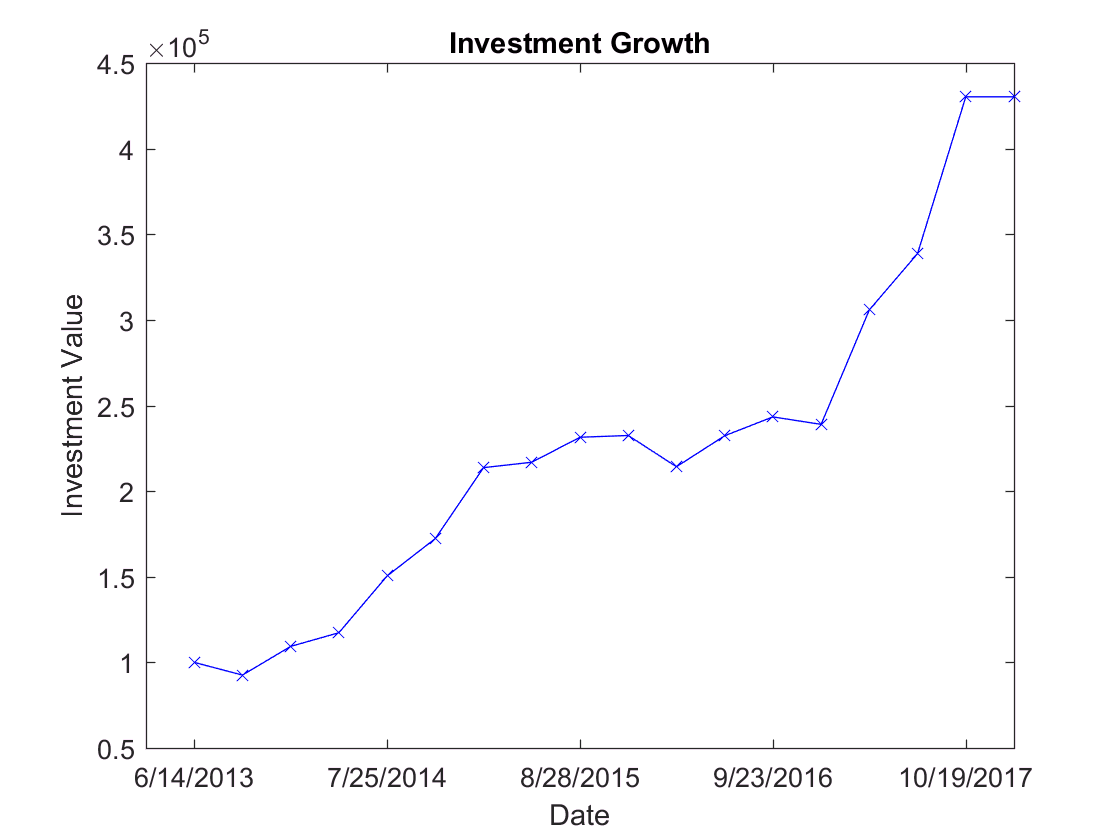

% for i = 1:size(asset_allocation_vector,2)
%     figure; plot(asset_allocation_vector{i})
%     
%     title("Allocation: " + stock_tickers{i} )
%     ax = gca;
%     ax.YAxis.Exponent = 5;
%     xtick_locations = linspace(1,size(price_dates_string,1),5);
%     xticks(xtick_locations)
%     xticklabels(price_dates_string(floor(xtick_locations)))
%     ylabel('Lakhs')
% end
%     
% for i = 1:size(asset_quantity_vector,2)
%     figure; plot(asset_quantity_vector{i})
%     title("Quantity: " + stock_tickers{i} )
%     xtick_locations = linspace(1,size(price_dates_string,1),5);
%     xticks(xtick_locations)
%     xticklabels(price_dates_string(floor(xtick_locations)))
%     ylabel('Shares')
% end
% 
h = figure; plot(budget_vector, '-bx' )
ax = gca;
ax.YAxis.Exponent = 5;
title('Investment Growth')
xtick_locations = linspace(1,size(price_dates_string,1),5);
xticks(xtick_locations)
xticklabels(price_dates_string(floor(xtick_locations)))
ylabel('Investment Value')
xlabel('Date')
saveas(h, 'C:/Users/vignesh.subramanian/Desktop/stockPredictor/plots/investmentgrowth', 'png')

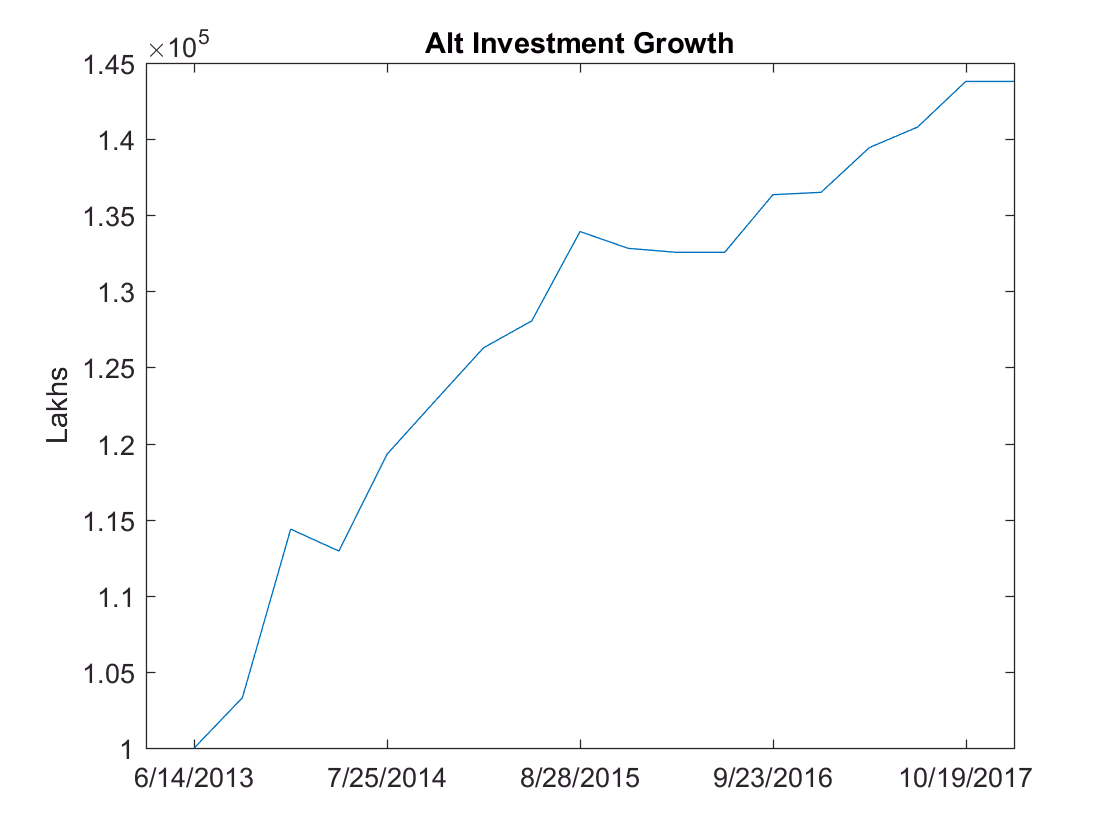


figure; plot(alt_budget_vector)
ax = gca;
ax.YAxis.Exponent = 5;
title('Alt Investment Growth')
xtick_locations = linspace(1,size(price_dates_string,1),5);
xticks(xtick_locations)
xticklabels(price_dates_string(floor(xtick_locations)))
ylabel('Lakhs')

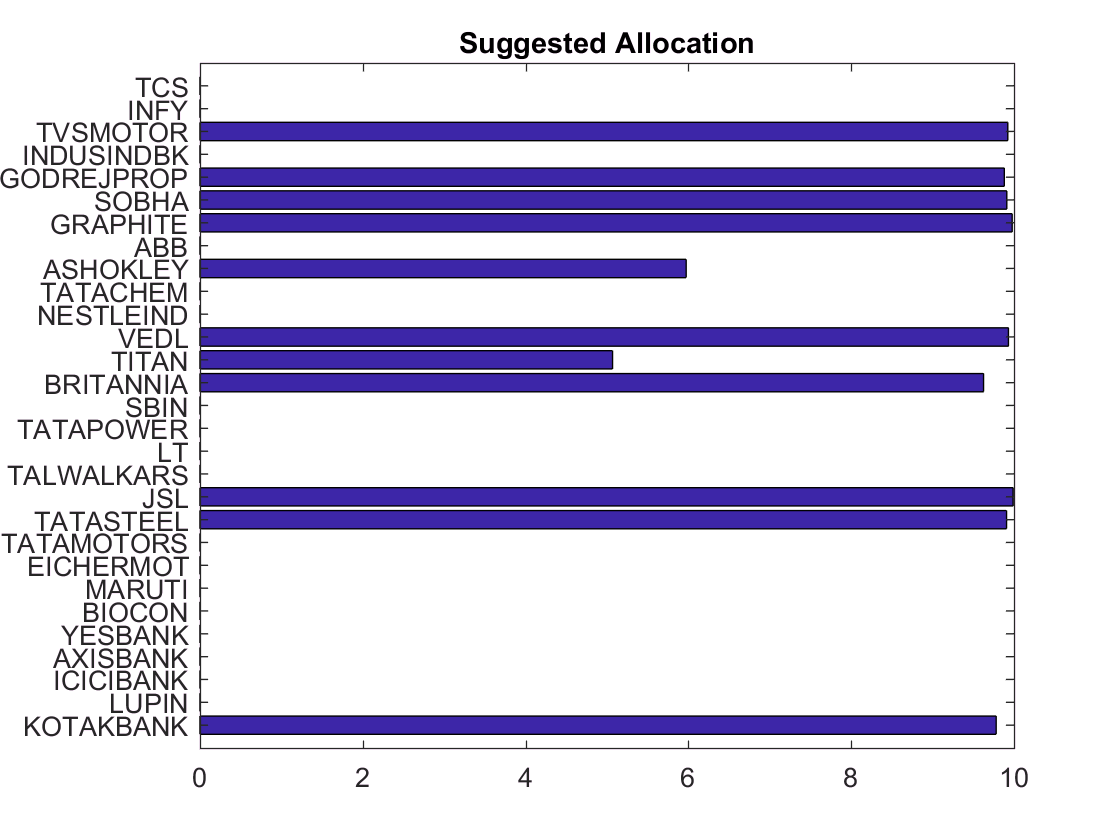



figure;barh(last_allocation)
title('Suggested Allocation')
yticks(1:size(stock_tickers,2))
yticklabels(stock_tickers)

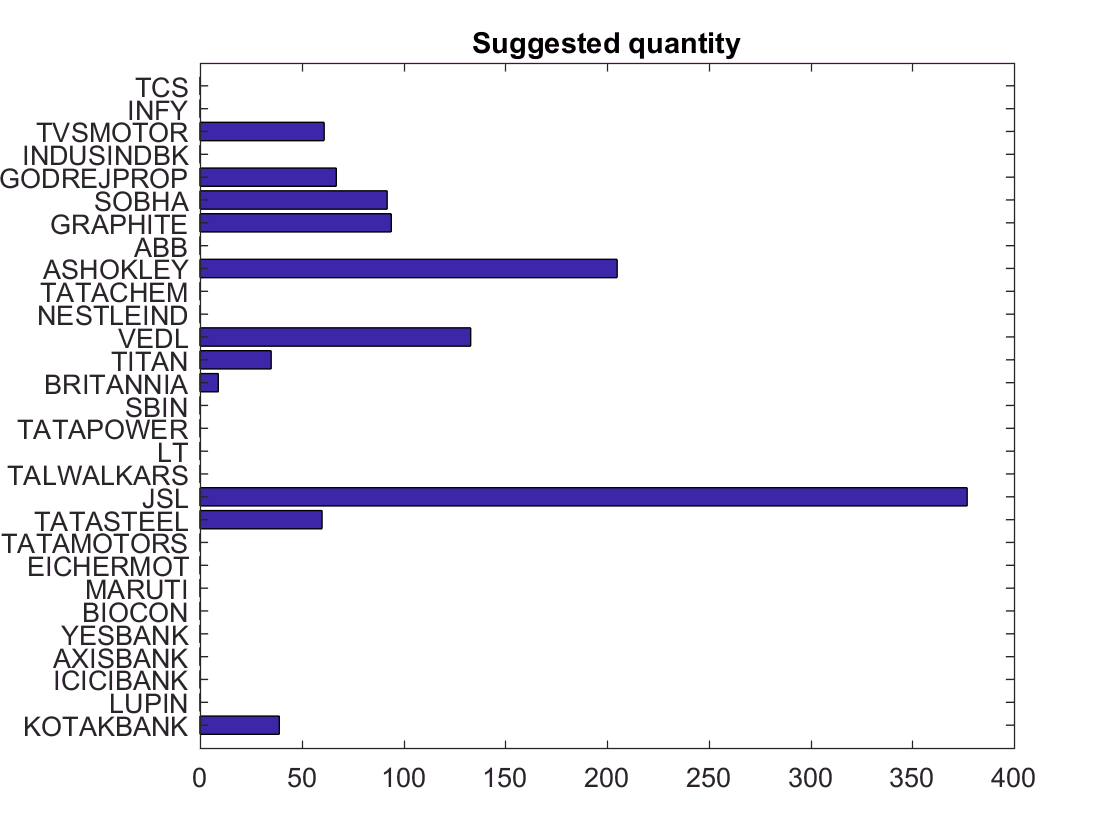



figure;barh(last_quantity)
title('Suggested quantity')
yticks(1:size(stock_tickers,2))
yticklabels(stock_tickers)

days_in_period = skip_weeks*7;
disp(" ")

disp("MIQP stratergy")

MIQP stratergy


[returns, sharpe_ratio] = get_stats(budget_vector, days_in_period)

overall_returns = 4.3025

mean_return = 9.5719

std_return = 11.9893

returns = 35.2466

sharpe_ratio = 0.7984

disp(" ")

disp("QP stratergy")

QP stratergy


[alt_returns, alt_sharpe_ratio] = get_stats(alt_budget_vector, days_in_period)

overall_returns = 1.4379

mean_return = 2.1974

std_return = 2.9117

alt_returns = 7.8044

alt_sharpe_ratio = 0.7547